# **Kalman Filter**

We decided to implement our time-varing Kalman Filter using this system design:

Given out time-varing system :

*x(t) *= *A*x(t*−1)+*B*u(t) *

*y(t) *=*C(t)*x(t)*+*D*ε(t)*

*where:*

A = identity matrix, i.e. w(i,t) = w(i,t-1) + random innovation;

B = diagonal matrix of unknown std.dev;

C(t) = returns of the Futures contracts, vector 1 x nAssets

D = volatility of target returns.

## Problem Introduction & Initial steps

clear;
clc;
close all;
load("InvestmentReplica.mat");

Our objective is to construct a portfolio that mirrors the performance of a specific market index, tailored for a young, financially savvy client aged 20-25. Given the client's extended investment horizon, the portfolio will be heavily weighted towards equities (≈ 80%), reflecting the historical success of long-term stock investments, as evidenced by indices like the MSCI World. To diversify risk and enhance stability, a minor allocation will be dedicated to bonds (≈ 15%) and other alternative assets (≈ 5%). This strategy acknowledges potential market downturns but leverages the long-term growth potential of a predominantly equity-based portfolio.

First of all we import the data and define our target index replica:

% Futures returns
X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(LLL1) price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1)];

% Synthetic target weights
wHFRXGL = 0.05; 
wMXWO = 0.8;
wLEGATRUU = 0.15;

% Building the target
y = wHFRXGL*price2ret(HFRXGL) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns


Now a simple plot to show our target:

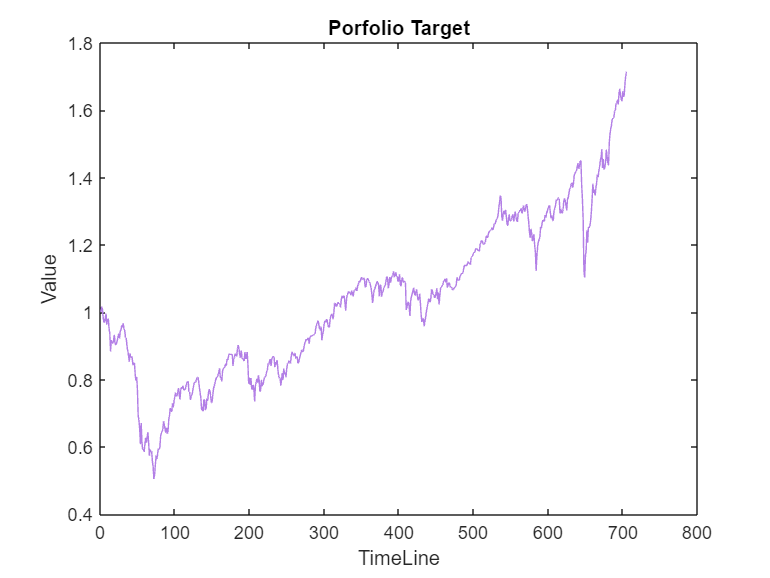

lilac = [0.7, 0.5, 0.9];  %color for the plots

%Portfolio Target
figure;
plot(ret2price(y), 'Color', lilac);
xlabel('TimeLine')
ylabel('Value')
title('Porfolio Target')

and our futures:

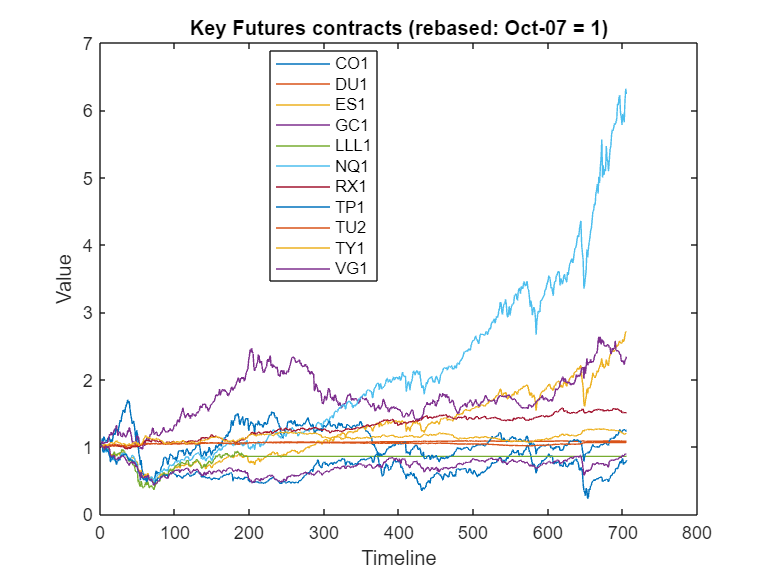

%Portfolio returns
figure;
plot(ret2price(X));
xlabel('Timeline')
ylabel('Value')
title('Key Futures contracts (rebased: Oct-07 = 1)')
names = { "CO1", "DU1", "ES1", "GC1", "LLL1", "NQ1", "RX1", "TP1", "TU2", "TY1", "VG1"};
legend(names, 'Location', 'best')

**CO1:** Brent Crude Oli Futures (ENERGY)

**DU1:** Euro-Schatz 2-Year Futures (INTEREST RATE)

**ES1:** S&P 500 E-Mini Futures (EQUITY)

**GC1:** Gold Futures Comex (METALS)

**LLL1: **?

**NQ1: **NASDAQ 100 E-Mini Futures (EQUITY)

**RX1:** Euro-Bund 10-Year Futures (INTEREST RATE)

**TP1:** TOPIX futures JPX (EQUITY)

**TU2: **?

**TY1: **US 2-Year T-Note Futures (INTEREST RATE)

**VG1: **EURO STOXX 50 Index Futures (EQUITY)

## Key variables and their initialization

First of all we have to inizialize the system parameters A,B and D, which are stationary.

[nObs, nAssets] = size(X) % Here we get the number of observations and the number of return assets

nObs = 704

nAssets = 11

A = eye(nAssets); % The state transition matrix is a square identity matrix
B = diag(0.1*ones(nAssets,1)); % The process noise matrix is a diagonal matrix
volatility = std(y);
D = volatility % The volatility of the target returns is a scalar value

D = 0.0200

The initialization of A is quite standard.

B is influenced by the weights that each assest has

Putting D=volatility  we get the value of the volatility of our Monster index.

To implement our filter we must compute 2 new parameters that are key to the Kalman Filter:

R=D^2 % Measurement noise covariance

R = 4.0157e-04

Q=B*B' % Process noise covariance

Q =     0.0100         0         0         0         0         0         0         0         0         0         0
         0    0.0100         0         0         0         0         0         0         0         0         0
         0         0    0.0100         0         0         0         0         0         0         0         0
         0         0         0    0.0100         0         0         0         0         0         0         0
         0         0         0         0    0.0100         0         0         0         0         0         0
         0         0         0         0         0    0.0100         0         0         0         0         0
         0         0         0         0         0         0    0.0100         0         0         0         0
         0         0         0         0         0         0         0    0.0100         0         0         0
         0         0         0         0         0         0         0         0    0.0100         0        

The calculation of the measurement noise covariance is quite straight forward, in fact since *ε(t)*~WN(0,1)  we get that  v_2=*D*ε(t) *~WN(0,D^2) thanks to the properties of White Noises. Hence: R= D^2.

The computation of the process noise is a bit less intuitive, we have to take into account more things. First of all we want our system to have the different noises to be indipendent from each other, using a diagonal matrix is the best way to show this property. Also it's better to have a small values of the process noise covariance, hence multiplying by our B matix, which for construction has a small value on the diagonal, helps to smooth the process and to help convergence.

## The Kalman Filter

The time-varing kalman filter takes into account the fact that the noise covariances are changing through the process, which is obviously the case in a wallet.

The main charachters of our implementation are:

- P(n) the error covariance which is updated through the DRE (Discrete-time Riccati Equation).

- K(n) the Kalman gain calculation which also varies with time.

- x_hat[n+1|n] the prediction state estimate at time n+1 given the information available up to and including time n.

- x_hat[n|n] the state update at time n given the information available up to time n (included).

The system of our Kalman Filter is the following:

           
$$\begin{array}{l}
\hat{x} \left\lbrack n+1\right|n\right\rbrack =A\cdot \hat{x} \left\lbrack n\left|n\right\rbrack +B\cdot u\left\lbrack n\right\rbrack +B\cdot w\left\lbrack n\right\rbrack \\
P\left\lbrack n+1\right|n\right\rbrack =A\cdot P\left\lbrack n\left|n\right\rbrack \cdot A^T +B\cdot Q\cdot B^T \\
K\left\lbrack n\right\rbrack =\frac{\left.P\left\lbrack n\right|n-1\right\rbrack \cdot C^T }{\left.C\cdot P\left\lbrack n\right|n-1\right\rbrack \cdot C^T +R}\\
\left.\hat{x} \left\lbrack n\right|n\right\rbrack =x\_\mathrm{hat}\left\lbrack n\left|n-1\right\rbrack +K\left\lbrack n\right\rbrack \cdot \left(y\left\lbrack n\right\rbrack -C\left\lbrack n\right\rbrack \cdot \hat{x} \left\lbrack n\right|n-1\right\rbrack \right)\\
P\left\lbrack n\right|n\right\rbrack =\left(1-K\left\lbrack n\right\rbrack \cdot C\left\lbrack n\right\rbrack \right)\cdot P\left\lbrack n\left|n-1\right\rbrack \\
\hat{y} \left\lbrack n\right|n\right\rbrack =C\left\lbrack n\right\rbrack \cdot \hat{x} \left\lbrack n\left|n\right\rbrack 
\end{array}$$


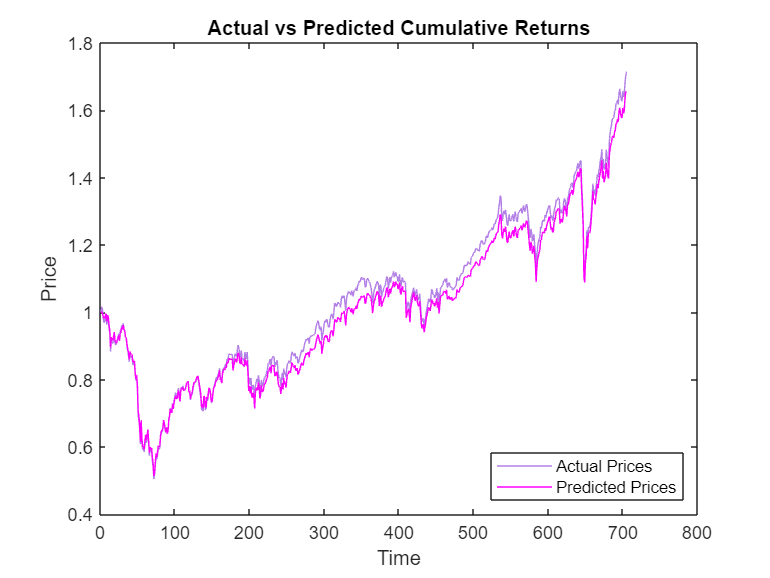

% Initial error covariance
P = B*Q*B';

% Initial condition on the state (weights of the portfolio)
weights = zeros(nAssets,1);

% Initializing the matrixes
estimatedWeights = zeros(nObs, nAssets);
y_hat = zeros(nObs,1);


for i=1:nObs
  
  % Initializing C[n]
  C=X(i,:);

  % Measurement update
  K = P*C'/(C*P*C'+R);                            % K[n]
  weights = weights + K*(y(i)-C*weights);      % x[n|n]
  P = (eye(nAssets)-K*C)*P;                       % P[n|n]
  y_hat(i) = C * weights;                             % y_hat[n|n]

  estimatedWeights(i, :)= weights';   % matrix to put our Weights
  
  % Time update
  u = 0.01*randn(nAssets, 1);               % random noise
  weights = A*weights + B*u;                % x[n+1|n]
  P = A*P*A' + Q;                           % P[n+1|n] 
 
end

% From returns to prices
truePrices=ret2price(y);
predictedPrices=ret2price(y_hat);

% Plot of y_hat (prediction) vs y (storic series)
figure;
plot(ret2price(y), 'Color', lilac);
hold on;
plot(ret2price(y_hat), 'm');
legend('Actual Prices', 'Predicted Prices', 'Location', 'southeast');
title('Actual vs Predicted Cumulative Returns');
xlabel('Time');
ylabel('Price');

## Weights plot

Let's plot the weights with a dynamic bar chart to observe how they vary over time.

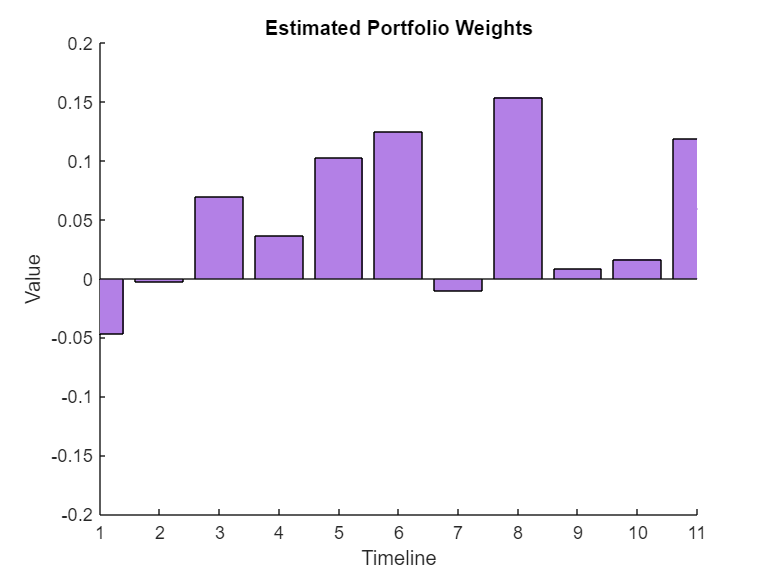

for ii = 1:nAssets
    clf;
    hold on;
    xlim([1, size(estimatedWeights, 2)]); % Imposta i limiti dell'asse x in base al numero di colonne in estimatedWeights
    ylim([-0.2 0.2]); % Imposta i limiti dell'asse y
    xlabel('Timeline')
    ylabel('Value')
    title('Estimated Portfolio Weights')
    yline(0);
    bar(estimatedWeights(ii,:), 'FaceColor', lilac);
    pause(0.2);
end
xlim([1, size(estimatedWeights, 2)]); % Imposta i limiti dell'asse x in base al numero di colonne in estimatedWeights
ylim([-0.2 0.2]); % Imposta i limiti dell'asse y
xlabel('Timeline')
ylabel('Value')
title('Estimated Portfolio Weights')

**Legend: { "CO1", "DU1", "ES1", "GC1", "LLL1", "NQ1", "RX1", "TP1", "TU2", "TY1", "VG1"};**

Now, let's create plots of weights over time.

Given our significant exposure in the stock market, specifically in the MSCI WORLD index, we can expect that equity futures, particularly those related to US (ES1, NQ1) and EU (VG1) markets heavily represented in the MSCI, will have positive weights. Conversely, since we have minimal exposure in the bond market, we expect a behavior of little significance (small/negative/volatile weights) for interest rate indices (e.g., TY1, RX1, DU1).  Energy (CO1) futures should not have significant influence while Gold (GC1), typically positively correlated with the performance of the US market, could have a positive influence on the replica.

## **ES1, NQ1, VG1**

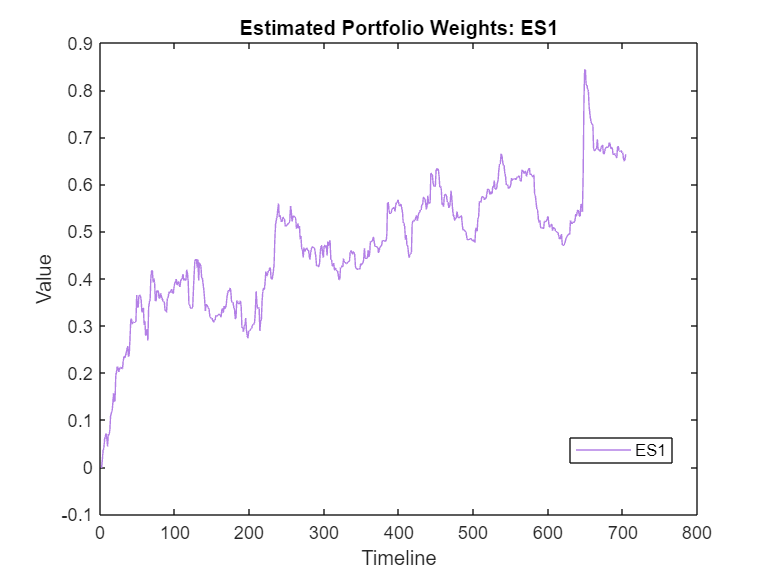

figure;
plot (estimatedWeights(:,3),'Color', lilac);
xlabel('Timeline')
ylabel('Value')
title('Estimated Portfolio Weights: ES1')
names = {"ES1"};
legend(names, 'Location', 'best')

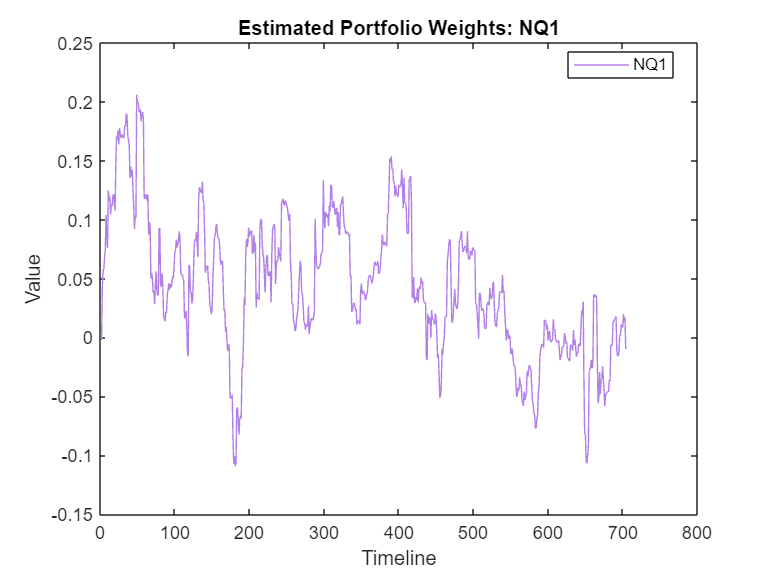

figure;
plot (estimatedWeights(:,6),'Color', lilac);
xlabel('Timeline')
ylabel('Value')
title('Estimated Portfolio Weights: NQ1')
names = {"NQ1"};
legend(names, 'Location', 'best')

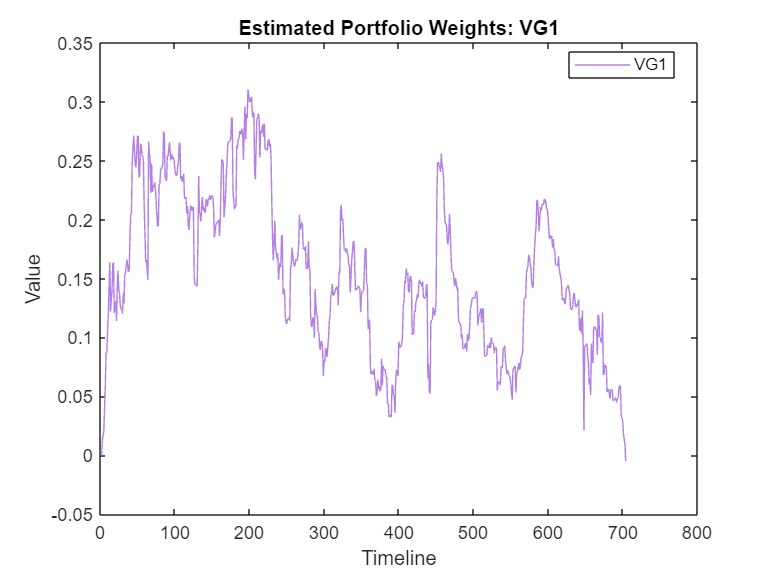

figure;
plot (estimatedWeights(:,11),'Color', lilac);
xlabel('Timeline')
ylabel('Value')
title('Estimated Portfolio Weights: VG1')
names = {"VG1"};
legend(names, 'Location', 'best')

## TY1, RX1, DU1

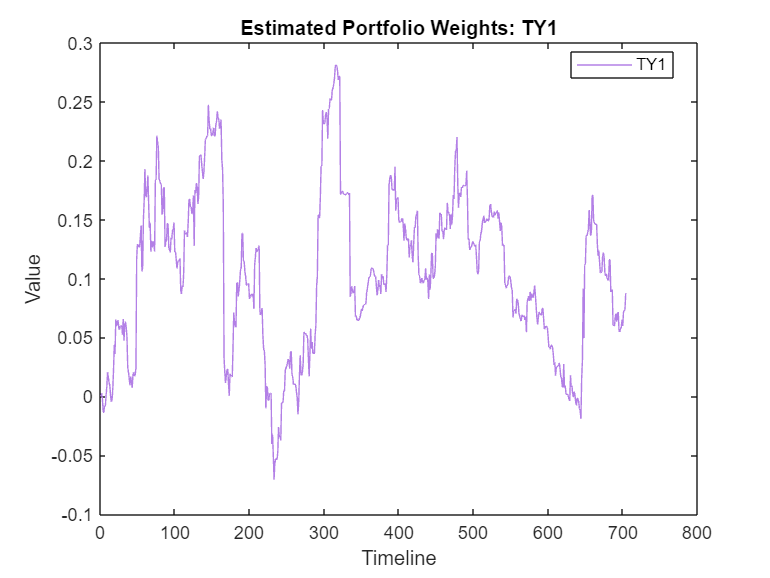

figure;
plot (estimatedWeights(:,10),'Color', lilac);
xlabel('Timeline')
ylabel('Value')
title('Estimated Portfolio Weights: TY1')
names = {"TY1"};
legend(names, 'Location', 'best')

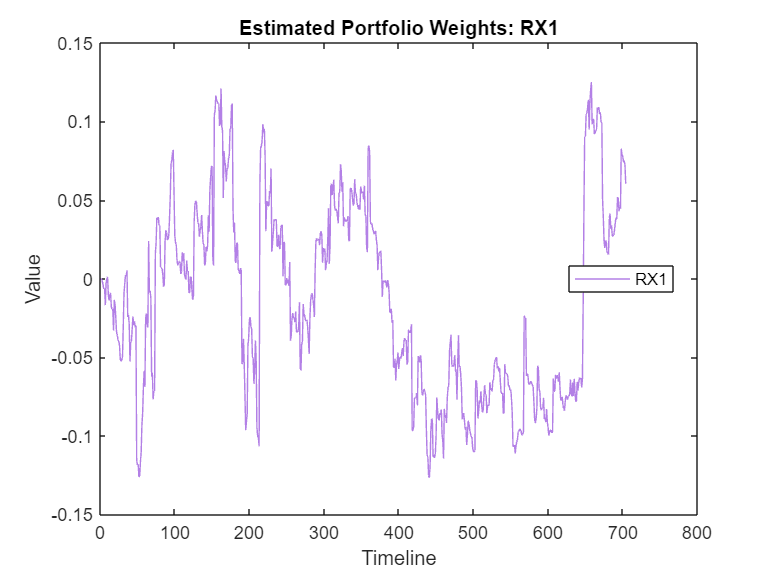

figure;
plot (estimatedWeights(:,7),'Color', lilac);
xlabel('Timeline')
ylabel('Value')
title('Estimated Portfolio Weights: RX1')
names = {"RX1"};
legend(names, 'Location', 'best')

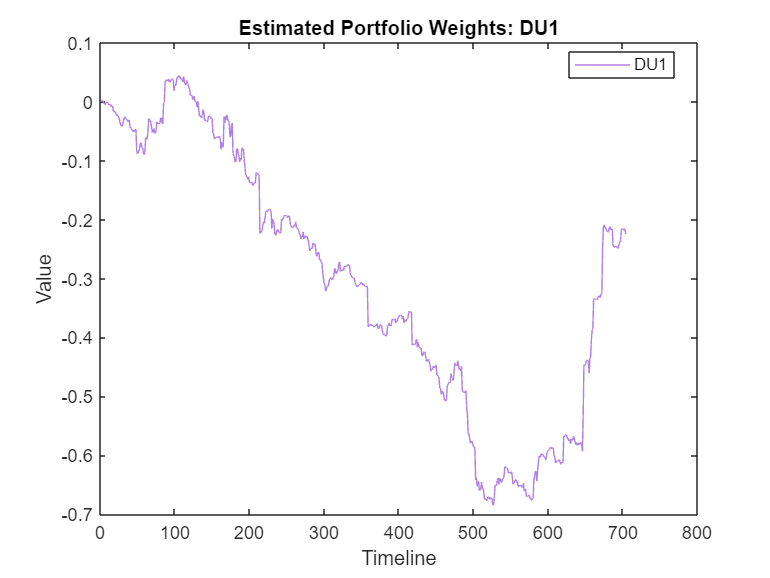

figure;
plot (estimatedWeights(:,2),'Color', lilac);
xlabel('Timeline')
ylabel('Value')
title('Estimated Portfolio Weights: DU1')
names = {"DU1"};
legend(names, 'Location', 'best')

## CO1, GC1

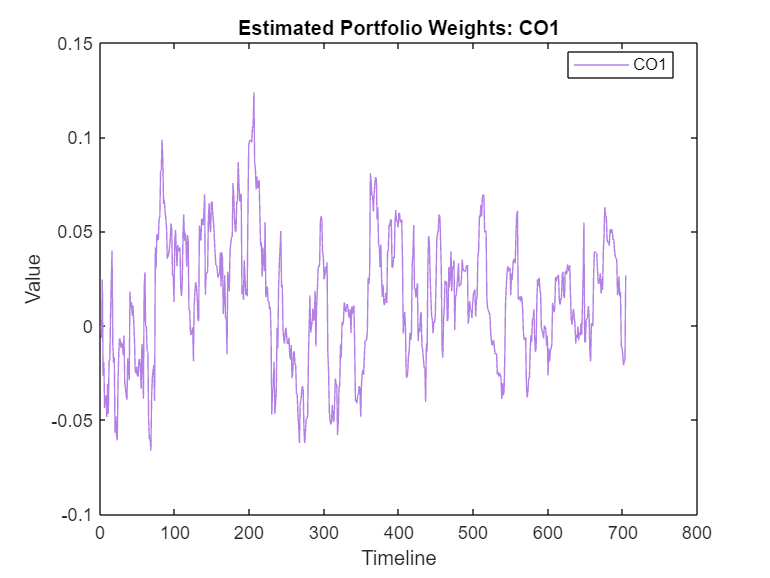

figure;
plot (estimatedWeights(:,1),'Color', lilac);
xlabel('Timeline')
ylabel('Value')
title('Estimated Portfolio Weights: CO1')
names = {"CO1"};
legend(names, 'Location', 'best')

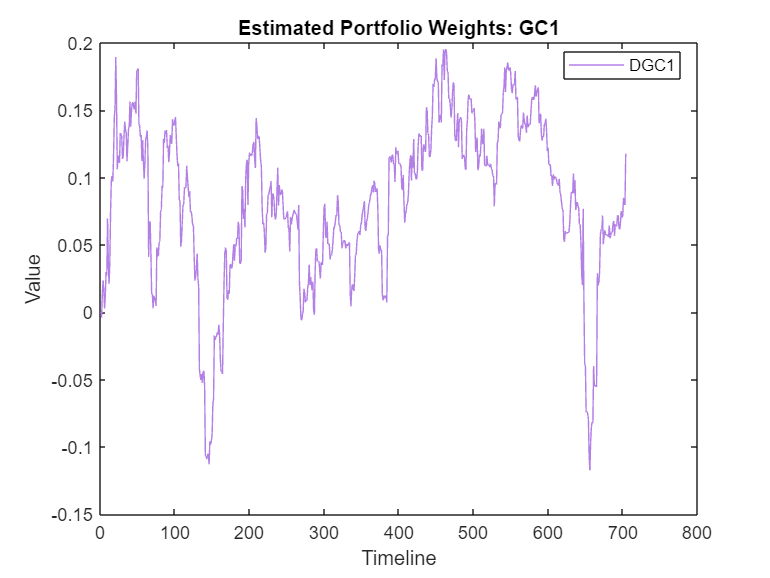

figure;
plot (estimatedWeights(:,4),'Color', lilac);
xlabel('Timeline')
ylabel('Value')
title('Estimated Portfolio Weights: GC1')
names = {"DGC1"};
legend(names, 'Location', 'best')

**Note: **When looking at the weight plots, the correlation between the Monster Index and Gold futures (GC1) can be pinpointed at a specific moment. Notably, when the Monster Index price plummets (in the timeline between 600 and 700), the weight of the Gold futures also drops. This indicates that when the Monster Index (primarily the MSCI World) decreases in value, shorting gold futures becomes advantageous in replicating the portfolio.

## Some financial metrics

Now let's evaluate some financial metrics useful for understanding the effectiveness of our replication (they will be used and compared with other models developed in RStudio)

## **MSE**

Average$L^2$-distance between true and predicted values

mse=mean((predictedPrices-truePrices).^2)

mse = 0.0010

## TEV

Volatility of the $L^1$-distance between true and predicted values

TE = truePrices-predictedPrices;
TEV = std(TE)*sqrt(52)

TEV = 0.1364

## Excess Return

Performance of the model measured in Euros [€]

logRClone = diff(log(predictedPrices));
logRTarget = diff(log(truePrices));
logTE =  logRClone - logRTarget;
meanTRTarget = exp(mean(logRTarget)*52) - 1

meanTRTarget = 0.0406

meanTRClone = exp(mean(logRClone)*52) - 1

meanTRClone = 0.0380

meanER = exp(mean(logTE)*52) - 1

meanER = -0.0026

## IR

Normalizing the mean measure with respect to the volatility measure we get a sharpness ratio

IR = meanER/TEV

IR = -0.0189

## Turnover

Let's estimate how much the portfolio has been traded during the year

Turnover =  sum(abs(diff(weights)),2)/2; % weekly turnover
meanTurnover = mean(Turnover)*52 % average annual turnover

meanTurnover = 7.0411

## Trading cost

We assume a transaction fee of 10 basis point and estimate the trading cost as a product of the fee and the average Turnover

tradingCosts = 0.001; 
meanTradingCosts = meanTurnover*tradingCosts

meanTradingCosts = 0.0070

NetTR = meanTRClone - meanTradingCosts

NetTR = 0.0309

NetER = meanER - meanTradingCosts

NetER = -0.0096

NetIR = NetER/TEV

NetIR = -0.0705

## References

Time-varing Kalman Filter: [https://it.mathworks.com/help/control/ug/kalman-filtering.html](https://it.mathworks.com/help/control/ug/kalman-filtering.html)

Model Identification and Data Analysis course